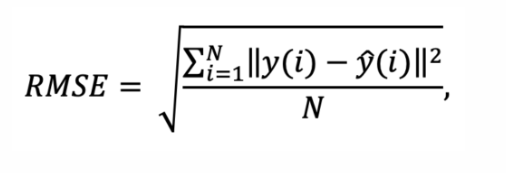

% RMSE
summ_cmd_3 = 0;
summ_cmd_4 = 0;
summ_cmd_10 =0;
sz = size(cmd3iter);

for ii=1:sz(1,1)
% Commands with 3 real time iterations compared to 10 real time iteration    
summ_cmd_3 = summ_cmd_3 + norm((cmd3iter(ii,1:4)'- cmd10iter(ii,1:4)'),2)^2;
% Commands with 4 real time iterations compared to 10 real time iteration 
summ_cmd_4 = summ_cmd_4 + norm((cmd4iter(ii,1:4)'- cmd10iter(ii,1:4)'),2)^2;
% 
%summ_cmd_10 = summ_cmd_10 + norm((cmd10iter(ii,1:4)'),2)^2;
end
RMSE_cmd_3 = sqrt(summ_cmd_3/sz(1,1))

RMSE_cmd_3 = 0.0730

RMSE_cmd_4 = sqrt(summ_cmd_4/sz(1,1))

RMSE_cmd_4 = 0.0035

%RMSE_cmd_10 = sqrt(summ_cmd_10/sz(1,1))

Percentage

% percentage
avg_cmd_10 = norm(sum(cmd10iter(:,1:4))/sz(1,1),2)

avg_cmd_10 = 3.7207

% Cmd_3
per_cmd_3 = (RMSE_cmd_3/avg_cmd_10)*100

per_cmd_3 = 1.9625

% Cmd_4
per_cmd_4 = (RMSE_cmd_4/avg_cmd_10)*100

per_cmd_4 = 0.0954